# Example: Plot Field Parameters

Information about the wave-physics of multi-layered structures can be gained by plotting the displacement and stress fields at different points. In ElasticMatrix, the angle, frequency and x-z range over which to plot the displacement or stress fields must be specified. The `.calculateField` method uses the x-z ranges to define a grid, calculates the displacement and stress for each point on the grid for a plane wave at the specified angle and frequency and returns the field parameters in a structure. The values of the structure can be plotted independently or given as an argument to the `.plotField` method.

## Initialize an `ElasticMatrix` Object

Initialize an `ElasticMatix` object, in this example it will be an aluminium plate in water.

% Medium class:
my_medium = Medium(...
    'water', Inf, 'aluminium', 0.001, 'water', Inf);

% Initialize an ElasticMatrix object:
my_model = ElasticMatrix(my_medium);

## Setting Calculation Parameters

In this example the aluminium plate is $1$mm thick, and the plotting ranges are set to be greater than this. The number of points in the plotting range vectors defines the plotting grid density. The Z-vector defines the plotting range across the thickness of each layer, and the X- vector is parallel to the interface of each layer. 

% Chosen angle and frequency:
plot_angle      = 19.99;    % [degrees]
plot_frequency  = 4.425e6;  % [MHz]

% Define plotting vectors, note the range of Z compared with the thickness
% of the aluminium plate:
sample_points = 128;
Z = linspace(-1.5e-3, 0.5e-3, sample_points); % [m]
X = linspace(-1.5e-3, 1.5e-3, sample_points); % [m]

## Calculating Field Parameters

Calculate the displacement and stress fields:

output_field = my_model.calculateField( ...
    plot_frequency, plot_angle, {Z, X});

... calculating displacement and stress fields ...
... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 
... finished calculating displacement and stress fields ...


## `output_field` Structure

`output_field` is a structure that contains: 

- `.z_displacement` - normal displacement field 

- `.x_displacemen`t - transverse displacement field 

- `.sigma_zz` normal stress field 

- `.sigma_xz` shear stress field 

- `.z_vector` of x-range 

- `.x_vector` of z-range

disp(output_field);

          z_vector: [1×128 double]
          x_vector: [1×128 double]
    x_displacement: [128×128 double]
    z_displacement: [128×128 double]
          sigma_zz: [128×128 double]
          sigma_xz: [128×128 double]


## Plotting the Field Parameters

The field can be plotted by passing the `output_field` structure to the .`plotField` method. 

Plot styles: 

- `'displacement1D' `

- `'displacement2D' `

- `'stress1D' `

- `'stress2D' `

- `'vector' `

- `'mesh' `

- `'surf' `

- `'all'`

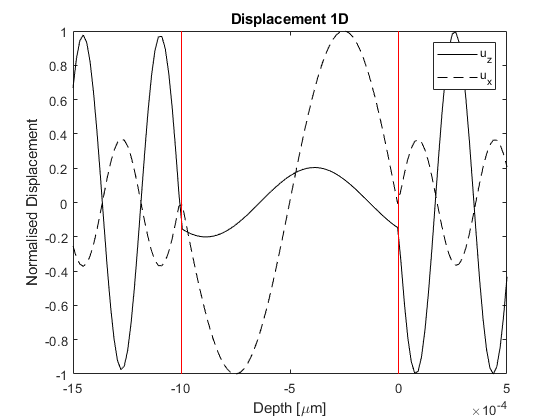

% To plot the normal and transverse displacement along the line x=0 z=Z_hf:
fig_hand = my_model.plotField(output_field, 'displacement1D');

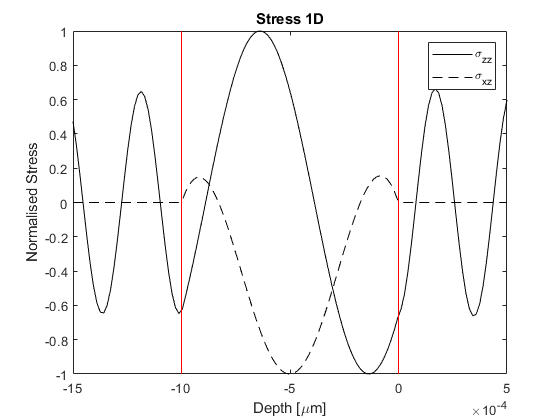

% To plot the normal and transverse displacement along the line x=0 z=Z_hf:
fig_hand = my_model.plotField(output_field, 'stress1D');

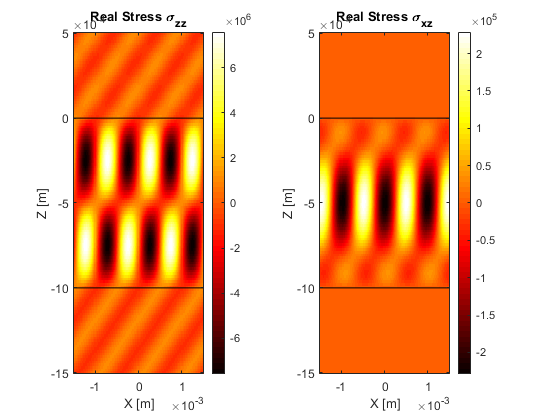

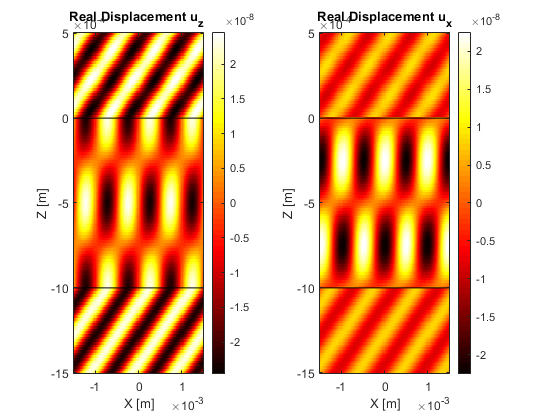

% To plot the 2D fields for displacement and stress:
fig_hand = my_model.plotField(output_field, 'displacement2D', 'stress2D');

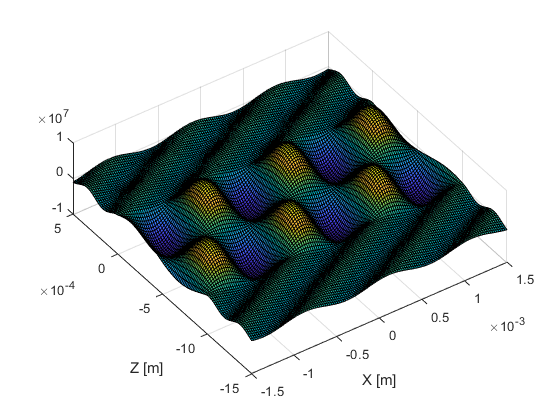

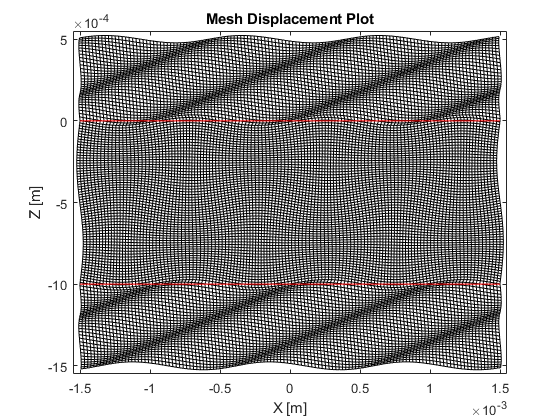

% To plot a mesh and surf plot of the displacement:
fig_hand = my_model.plotField(output_field, 'mesh', 'surf');

You can give multiple arguments to .`plotfield`, for example: `fig_hand = my_model.plotField(output_field, 'mesh', 'surf',..., 'displacement1D');`

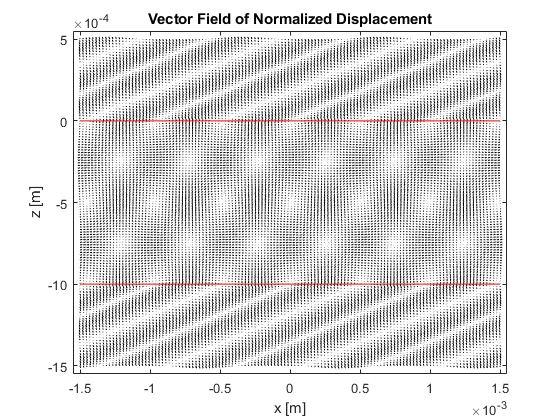

% To plot every style:
fig_hand = my_model.plotField(output_field, 'all');

## Passing a Figure Handle

For some uses, like when creating a movie of the displacement field, the user may require multiple figures to be plotted over the same figure axes. The .`plotField` method can take an input argument of a figure handle to prevent new figure axes being created. An example is shown here, showing the displacement field at different time intervals on the same figure axes.

% Firstly calculate the field at t = 0:
time = 0e-6;
output_field = my_model.calculateField(...
    plot_frequency, plot_angle, {Z, X}, time);

... calculating displacement and stress fields ...
... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 
... finished calculating displacement and stress fields ...


Plot the figure with the input arguments for the plot-style, this creates two new figures where the handles are assigned to `new_handle.mesh` and `new_handle.surf`.

new_figure_handle = my_model.plotField(output_field, 'mesh', 'surf');

disp(new_figure_handle)

    surf: [1×1 Figure]
    mesh: [1×1 Figure]


% Calculate the updated field at t = 0.1e-6 s:
time = 0.1e-6;
updated_field = my_model.calculateField(...
    plot_frequency, plot_angle, {Z, X}, time);

... calculating displacement and stress fields ...
... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 
... finished calculating displacement and stress fields ...


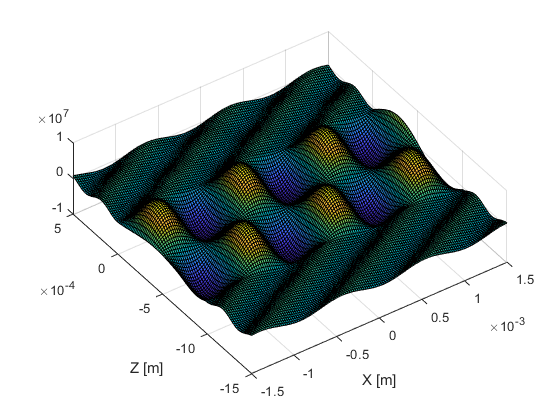

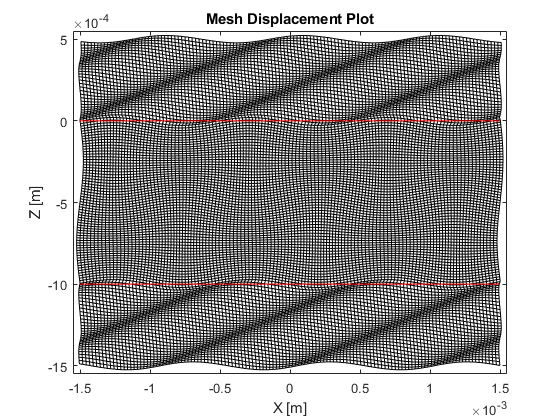

% Passing the updated_field structure and the figure handle updates the
% figures axes: 
new_figure_handle = my_model.plotField(updated_field, new_figure_handle);